
clear;

profile = Profile.ski;

if profile == Profile.walk
    clockTimeLimit = 100; % 体験時間 (s)
    period = 6; % 歩行周期 (s)
    
    legForwardTimeRate = 2; % 足スライダ前進 時間比
    legBackwardTimeRate = 3; % 足スライダ後退 時間比
    
    stockForwardTimeRate = 2; % ストックスライダ前進 時間比
    stockBackwardTimeRate = 3; % ストックスライダ後退 時間比
    
    upTimeRate = 5; % 伸縮 持ち上げ 時間比
    downTimeRate = 1; % 伸縮 降下 時間比
    
    stockFlyingTimeRate = 2.2; % ストック空中時間比
    stockGroundTimeRate = 2.8; % ストック接地時間比
    
    tiltBackwardTimeRate = 1.8;
    tiltForwardTimeRate = 3.2;
    
    liftLength = 40; % 椅子 リフト長 単位 (mm)
    pedalLength = 60; % ペダル長 単位 (mm)
    seatSlideForwardLength = 200; % 椅子 スライド長 単位 (mm)
    seatSlideBackwardLength = 50; % 椅子 スライド長 単位 (mm)
    extendLength = 100; % 伸縮長 単位 (mm)
    stockSlideForwardLength = 100; % ストック スライド前方向長 単位 (mm)
    stockSlideBackwardLength = 450; % ストック スライド後方向長 単位 (mm)
    tiltBackwardDeg = 5; % ストック 後傾角度 (deg)
    tiltForwardDeg = -30; % ストック 前傾角度 (deg)
elseif (profile == Profile.ski || profile == Profile.doubleStock)
    clockTimeLimit = 100; % 体験時間 (s)
    period = 6; % 歩行周期 (s)
    
    legForwardTimeRate = 3; % 足スライダ前進 時間比
    legBackwardTimeRate = 2; % 足スライダ後退 時間比
    
    stockForwardTimeRate = 3; % ストックスライダ前進 時間比
    stockBackwardTimeRate = 2; % ストックスライダ後退 時間比
    
    upTimeRate = 5; % 伸縮 持ち上げ 時間比
    downTimeRate = 1; % 伸縮 降下 時間比
    
    stockFlyingTimeRate = 3.2; % ストック空中時間比
    stockGroundTimeRate = 1.8; % ストック接地時間比
    
    tiltBackwardTimeRate = 2;
    tiltForwardTimeRate = 3;
    
    liftLength = 30; % 椅子 リフト長 単位 (mm)
    pedalLength = 60; % ペダル長 単位 (mm)
    seatSlideForwardLength = 200; % 椅子 スライド長 単位 (mm)
    seatSlideBackwardLength = 50; % 椅子 スライド長 単位 (mm)
    extendLength = 300; % 伸縮長 単位 (mm)
    stockSlideForwardLength = 100; % ストック スライド前方向長 単位 (mm)
    stockSlideBackwardLength = 450; % ストック スライド後方向長 単位 (mm)
    tiltBackwardDeg = 5; % ストック 後傾角度 (deg)
    tiltForwardDeg = -30; % ストック 前傾角度 (deg)
elseif profile == Profile.doubleStockOnly
    clockTimeLimit = 100; % 体験時間 (s)
    period = 6; % 歩行周期 (s)
    
    legForwardTimeRate = 2; % 足スライダ前進 時間比
    legBackwardTimeRate = 3; % 足スライダ後退 時間比
    
    stockForwardTimeRate = 3; % ストックスライダ前進 時間比
    stockBackwardTimeRate = 2; % ストックスライダ後退 時間比
    
    upTimeRate = 5; % 伸縮 持ち上げ 時間比
    downTimeRate = 1; % 伸縮 降下 時間比
    
    stockFlyingTimeRate = 3.2; % ストック空中時間比
    stockGroundTimeRate = 1.8; % ストック接地時間比
    
    tiltBackwardTimeRate = 2;
    tiltForwardTimeRate = 3;
    
    liftLength = 30; % 椅子 リフト長 単位 (mm)
    pedalLength = 60; % ペダル長 単位 (mm)
    seatSlideForwardLength = 200; % 椅子 スライド長 単位 (mm)
    seatSlideBackwardLength = 50; % 椅子 スライド長 単位 (mm)
    extendLength = 300; % 伸縮長 単位 (mm)
    stockSlideForwardLength = 100; % ストック スライド前方向長 単位 (mm)
    stockSlideBackwardLength = 450; % ストック スライド後方向長 単位 (mm)
    tiltBackwardDeg = 5; % ストック 後傾角度 (deg)
    tiltForwardDeg = -30; % ストック 前傾角度 (deg)
end

椅子 リフト

lifter = 65×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       3.6          1.2              30                0      
       4.8          1.2               0                0      
       6.6          1.2              30                0      
       7.8          1.2               0                0      
       9.6          1.2              30                0      
      10.8          1.2               0                0      
      12.6          1.2              30                0      
      13.8          1.2               0                0      
      15.6          1.2              30                0      
      16.8          1.2               0                0      
      18.6          1.2              30                0      
      19.8          1.2               0                0      
      21.6          1.2              30                0      
      22.8          1.2           

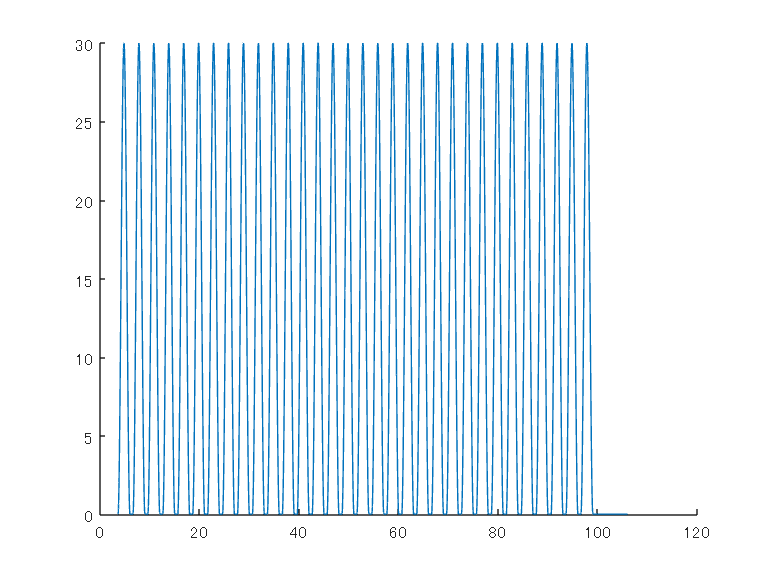

if profile ~= Profile.doubleStockOnly
    L = liftLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    if legForwardTimeRate < legBackwardTimeRate
        clockTimeU = 0; % 単位 (s)
        clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
        deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
        deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    else
        clockTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
        clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
        deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
        deltaTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    end
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)
    
    clockTimeUList = (startClockTime + clockTimeU):period/2:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period/2:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    lifter = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(lifter, "lifter.csv");
    figure;
    [lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);
elseif profile == Profile.doubleStockOnly
    L = liftLength; % スライド長 単位 (mm)
    startClockTime = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) / 2; % 単位 (s)
    deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) / 2; % 単位 (s)
    deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) / 2; % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)
    
    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    lifter = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(lifter, "lifter.csv");
    figure;
    [lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);
end

左ペダル

if profile ~=  Profile.doubleStockOnly
    L = pedalLength; % スライド長 単位 (mm)
    startClockTime = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)
    
    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    leftPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(leftPedal, "leftPedal.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

    L = pedalLength; % スライド長 単位 (mm)
    startClockTime = period/2 + period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)
    
    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    rightPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(rightPedal, "rightPedal.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

    startClockTime = 0; % 開始時刻 (s)
    clockTimeF = 0; % 単位 (s)
    clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    positionF = seatSlideForwardLength; % 単位 (mm)
    positionB = -seatSlideBackwardLength; % 単位 (mm)
    
    clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeFList; clockTimeBList];
    clockTime = tmp(:);
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    tmp = [deltaTimeFList; deltaTimeBList];
    deltaTime = tmp(:);
    positionFList = positionF + 0*clockTimeFList;
    positionBList = positionB + 0*clockTimeBList;
    tmp = [positionFList; positionBList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    seatLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(seatLeftSlider, "seatLeftSlider.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　右　スライダ

    startClockTime = period/2; % 開始時刻 (s)
    clockTimeF = 0; % 単位 (s)
    clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    positionF = seatSlideForwardLength; % 単位 (mm)
    positionB = -seatSlideBackwardLength; % 単位 (mm)
    
    clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeFList; clockTimeBList];
    clockTime = tmp(:);
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    tmp = [deltaTimeFList; deltaTimeBList];
    deltaTime = tmp(:);
    positionFList = positionF + 0*clockTimeFList;
    positionBList = positionB + 0*clockTimeBList;
    tmp = [positionFList; positionBList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    seatRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(seatRightSlider, "seatRightSlider.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);
elseif profile == Profile.doubleStockOnly
    L = pedalLength; % スライド長 単位 (mm)
    startClockTime = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) / 2; % 単位 (s)
    deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) / 2; % 単位 (s)
    deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) / 2; % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)
    
    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    leftPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(leftPedal, "leftPedal.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

    L = pedalLength; % スライド長 単位 (mm)
    startClockTime = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) / 2; % 単位 (s)
    deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) / 2; % 単位 (s)
    deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) / 2; % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)
    
    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    rightPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(rightPedal, "rightPedal.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

    startClockTime = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
    clockTimeF = 0; % 単位 (s)
    clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    positionF = seatSlideForwardLength; % 単位 (mm)
    positionB = -seatSlideBackwardLength; % 単位 (mm)
    
    clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeFList; clockTimeBList];
    clockTime = tmp(:);
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    tmp = [deltaTimeFList; deltaTimeBList];
    deltaTime = tmp(:);
    positionFList = positionF + 0*clockTimeFList;
    positionBList = positionB + 0*clockTimeBList;
    tmp = [positionFList; positionBList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    seatLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(seatLeftSlider, "seatLeftSlider.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　右　スライダ

leftPedal = 33×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       3.6          2.4              60                0      
         6          3.6               0                0      
       9.6          2.4              60                0      
        12          3.6               0                0      
      15.6          2.4              60                0      
        18          3.6               0                0      
      21.6          2.4              60                0      
        24          3.6               0                0      
      27.6          2.4              60                0      
        30          3.6               0                0      
      33.6          2.4              60                0      
        36          3.6               0                0      
      39.6          2.4              60                0      
        42          3.6        

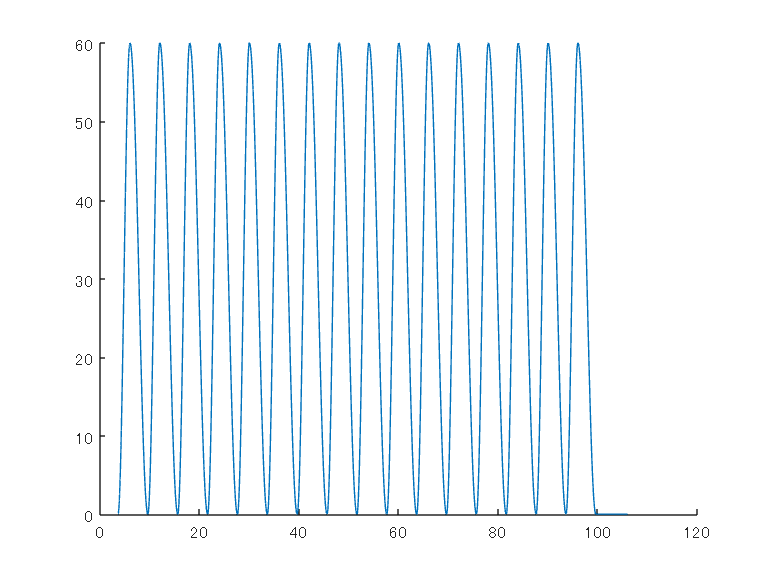

rightPedal = 33×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       6.6          2.4              60                0      
         9          3.6               0                0      
      12.6          2.4              60                0      
        15          3.6               0                0      
      18.6          2.4              60                0      
        21          3.6               0                0      
      24.6          2.4              60                0      
        27          3.6               0                0      
      30.6          2.4              60                0      
        33          3.6               0                0      
      36.6          2.4              60                0      
        39          3.6               0                0      
      42.6          2.4              60                0      
        45          3.6       

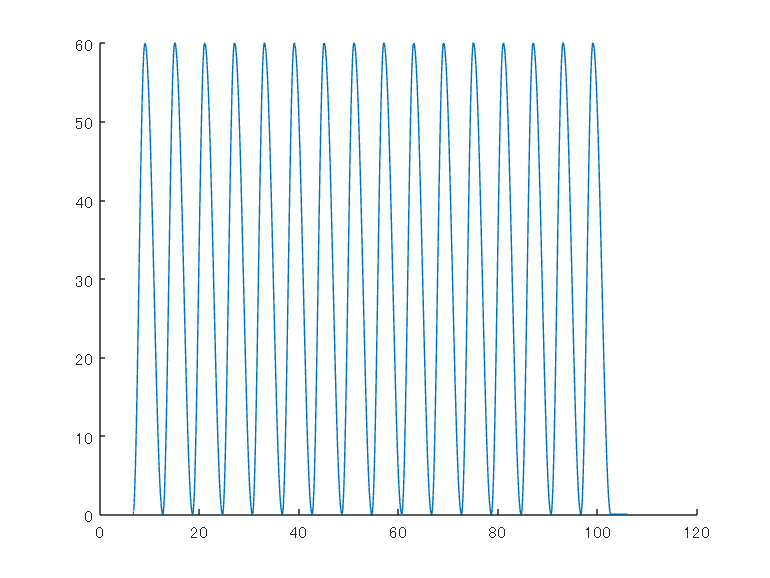

seatLeftSlider = 35×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0          3.6             200                0      
       3.6          2.4             -50                0      
         6          3.6             200                0      
       9.6          2.4             -50                0      
        12          3.6             200                0      
      15.6          2.4             -50                0      
        18          3.6             200                0      
      21.6          2.4             -50                0      
        24          3.6             200                0      
      27.6          2.4             -50                0      
        30          3.6             200                0      
      33.6          2.4             -50                0      
        36          3.6             200                0      
      39.6          2.4   

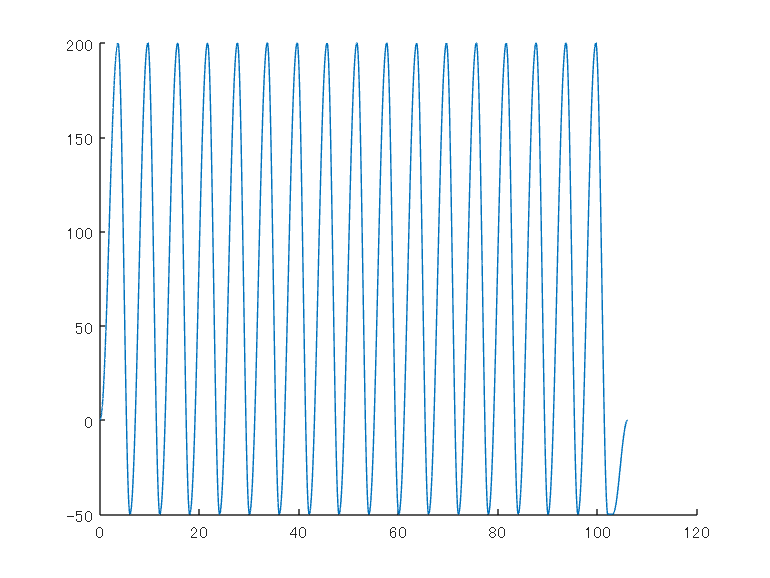

seatRightSlider = 33×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         3          3.6             200                0      
       6.6          2.4             -50                0      
         9          3.6             200                0      
      12.6          2.4             -50                0      
        15          3.6             200                0      
      18.6          2.4             -50                0      
        21          3.6             200                0      
      24.6          2.4             -50                0      
        27          3.6             200                0      
      30.6          2.4             -50                0      
        33          3.6             200                0      
      36.6          2.4             -50                0      
        39          3.6             200                0      
      42.6          2.4  

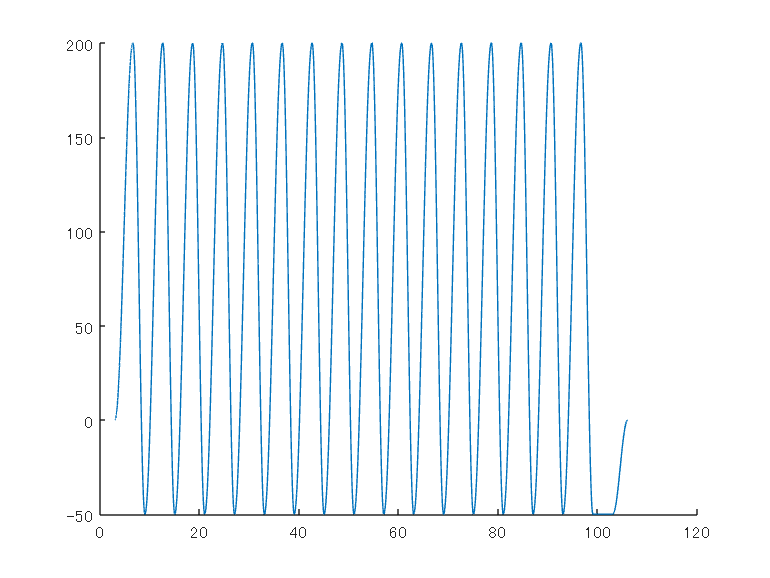

    startClockTime = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
    clockTimeF = 0; % 単位 (s)
    clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    positionF = seatSlideForwardLength; % 単位 (mm)
    positionB = -seatSlideBackwardLength; % 単位 (mm)
    
    clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeFList; clockTimeBList];
    clockTime = tmp(:);
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    tmp = [deltaTimeFList; deltaTimeBList];
    deltaTime = tmp(:);
    positionFList = positionF + 0*clockTimeFList;
    positionBList = positionB + 0*clockTimeBList;
    tmp = [positionFList; positionBList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    seatRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(seatRightSlider, "seatRightSlider.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);
end

if profile == Profile.walk

左ストックの伸縮　登山

    L = extendLength; % スライド長 単位 (mm)
    startClockTime = period/2; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeU = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);
    tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList))];
    useStiffness = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    useStiffness(end+1) = 0;

    stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockLeftExtend, "stockLeftExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　登山


    L = extendLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeU = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);
    tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList))];
    useStiffness = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    useStiffness(end+1) = 0;

    stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockRightExtend, "stockRightExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

elseif profile == Profile.ski

左ストックの伸縮 クロスカントリー


    L = extendLength; % スライド長 単位 (mm)
    startClockTime = period/2; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) + 0.1; % 単位 (s)
    deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) - 0.1; % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 2*L/3; % 単位 (mm)
    positionSlowD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
    tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
    tmp = [positionUList; positionDList; positionSlowDList];
    absolutePosition = tmp(:);

    tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList)); zeros(size(clockTimeSlowDList));];
    useStiffness = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    useStiffness(end+1) = 0;

    stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockLeftExtend, "stockLeftExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　クロスカントリー


    L = extendLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) + 0.1; % 単位 (s)
    deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) - 0.1; % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 2*L/3; % 単位 (mm)
    positionSlowD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
    tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
    tmp = [positionUList; positionDList; positionSlowDList];
    absolutePosition = tmp(:);
    tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList)); zeros(size(clockTimeSlowDList));];
    useStiffness = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    useStiffness(end+1) = 0;

    stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockRightExtend, "stockRightExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);
elseif (profile == Profile.doubleStock) || (profile == Profile.doubleStockOnly)
    L = extendLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) + 0.1; % 単位 (s)
    deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) - 0.1; % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 2*L/3; % 単位 (mm)
    positionSlowD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
    tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
    tmp = [positionUList; positionDList; positionSlowDList];
    absolutePosition = tmp(:);

    tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList)); zeros(size(clockTimeSlowDList));];
    useStiffness = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    useStiffness(end+1) = 0;

    stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockLeftExtend, "stockLeftExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮

stockLeftExtend = 49×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          3         3.2             300                0      
        6.2        0.64             200                1      
       6.94        2.06               0                0      
          9         3.2             300                0      
       12.2        0.64             200                1      
      12.94        2.06               0                0      
         15         3.2             300                0      
       18.2        0.64             200                1      
      18.94        2.06               0                0      
         21         3.2             300                0      
       24.2        0.64             200                1      
      24.94        2.06               0                0      
         27         3.2             300                0      
       30.2        0.64  

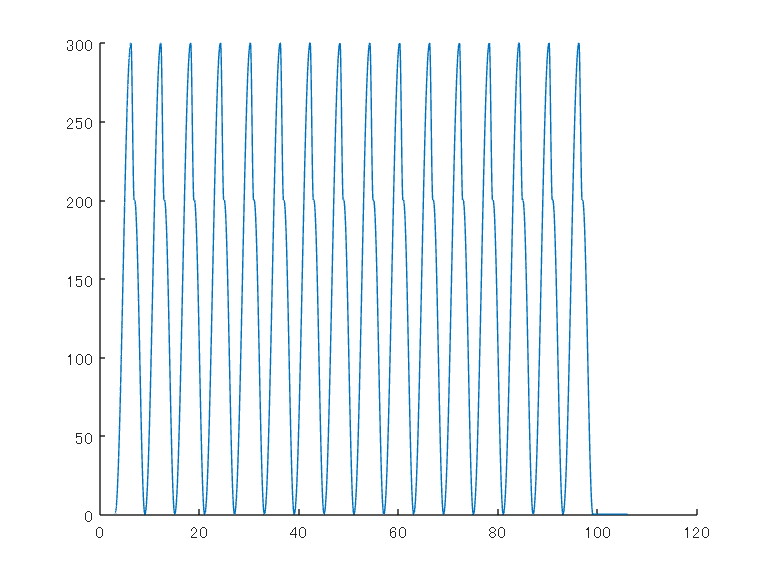

stockRightExtend = 52×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0         3.2             300                0      
        3.2        0.64             200                1      
       3.94        2.06               0                0      
          6         3.2             300                0      
        9.2        0.64             200                1      
       9.94        2.06               0                0      
         12         3.2             300                0      
       15.2        0.64             200                1      
      15.94        2.06               0                0      
         18         3.2             300                0      
       21.2        0.64             200                1      
      21.94        2.06               0                0      
         24         3.2             300                0      
       27.2        0.64 

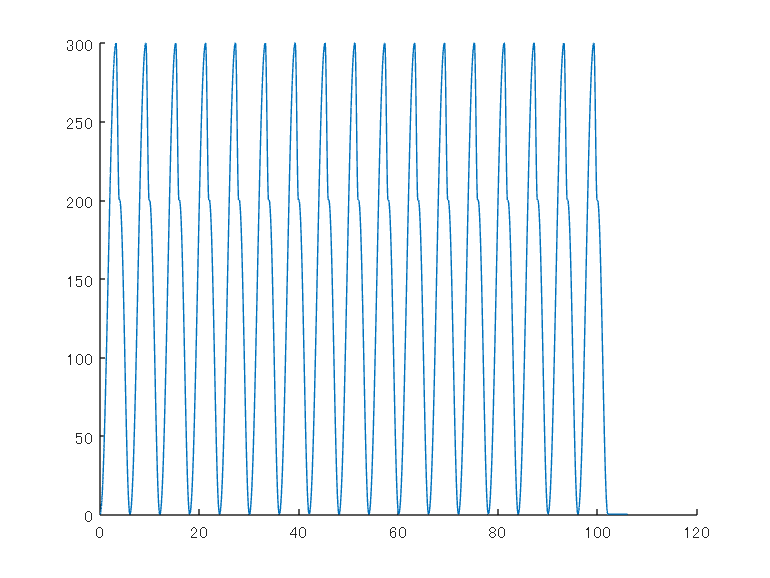


    L = extendLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) + 0.1; % 単位 (s)
    deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) - 0.1; % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 2*L/3; % 単位 (mm)
    positionSlowD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
    tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
    tmp = [positionUList; positionDList; positionSlowDList];
    absolutePosition = tmp(:);
    tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList)); zeros(size(clockTimeSlowDList));];
    useStiffness = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    useStiffness(end+1) = 0;

    stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockRightExtend, "stockRightExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);
end

左ストックのスライダ

if (profile ~= Profile.doubleStock) && (profile ~= Profile.doubleStockOnly)
    startClockTime = period/2; % 開始時刻 (s)
    clockTimeF = 0; % 単位 (s)
    clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    positionF = stockSlideForwardLength; % 単位 (mm)
    positionB = -stockSlideBackwardLength; % 単位 (mm)
    
    clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeFList; clockTimeBList];
    clockTime = tmp(:);
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    tmp = [deltaTimeFList; deltaTimeBList];
    deltaTime = tmp(:);
    positionFList = positionF + 0*clockTimeFList;
    positionBList = positionB + 0*clockTimeBList;
    tmp = [positionFList; positionBList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockLeftSlider, "stockLeftSlider.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ

    
    L = stockSlideForwardLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeF = 0; % 単位 (s)
    clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    positionF = stockSlideForwardLength; % 単位 (mm)
    positionB = -stockSlideBackwardLength; % 単位 (mm)
    
    clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeFList; clockTimeBList];
    clockTime = tmp(:);
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    tmp = [deltaTimeFList; deltaTimeBList];
    deltaTime = tmp(:);
    positionFList = positionF + 0*clockTimeFList;
    positionBList = positionB + 0*clockTimeBList;
    tmp = [positionFList; positionBList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    stockRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockRightSlider, "stockRightSlider.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);
elseif (profile == Profile.doubleStock) || (profile == Profile.doubleStockOnly)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeF = 0; % 単位 (s)
    clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    positionF = stockSlideForwardLength; % 単位 (mm)
    positionB = -stockSlideBackwardLength; % 単位 (mm)
    
    clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeFList; clockTimeBList];
    clockTime = tmp(:);
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    tmp = [deltaTimeFList; deltaTimeBList];
    deltaTime = tmp(:);
    positionFList = positionF + 0*clockTimeFList;
    positionBList = positionB + 0*clockTimeBList;
    tmp = [positionFList; positionBList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockLeftSlider, "stockLeftSlider.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ

stockLeftSlider = 33×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         3          3.6              100               0      
       6.6          2.4             -450               0      
         9          3.6              100               0      
      12.6          2.4             -450               0      
        15          3.6              100               0      
      18.6          2.4             -450               0      
        21          3.6              100               0      
      24.6          2.4             -450               0      
        27          3.6              100               0      
      30.6          2.4             -450               0      
        33          3.6              100               0      
      36.6          2.4             -450               0      
        39          3.6              100               0      
      42.6          2.4  

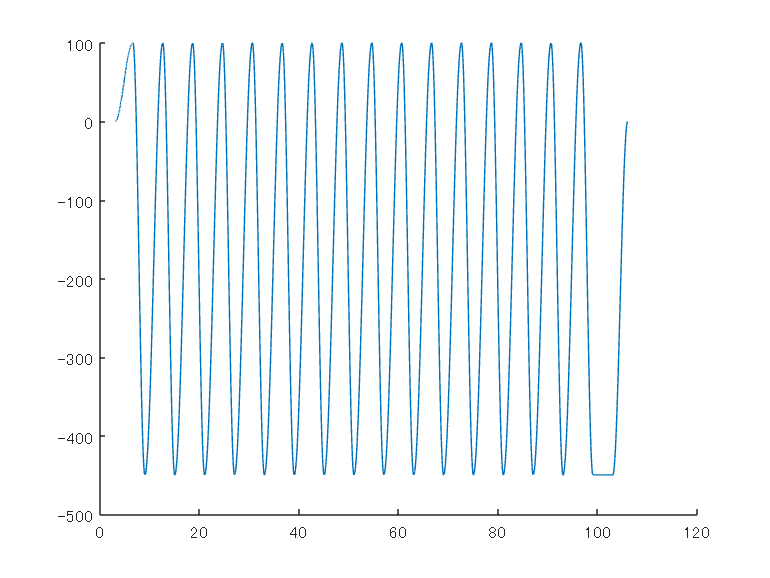

stockRightSlider = 35×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0          3.6              100               0      
       3.6          2.4             -450               0      
         6          3.6              100               0      
       9.6          2.4             -450               0      
        12          3.6              100               0      
      15.6          2.4             -450               0      
        18          3.6              100               0      
      21.6          2.4             -450               0      
        24          3.6              100               0      
      27.6          2.4             -450               0      
        30          3.6              100               0      
      33.6          2.4             -450               0      
        36          3.6              100               0      
      39.6          2.4 

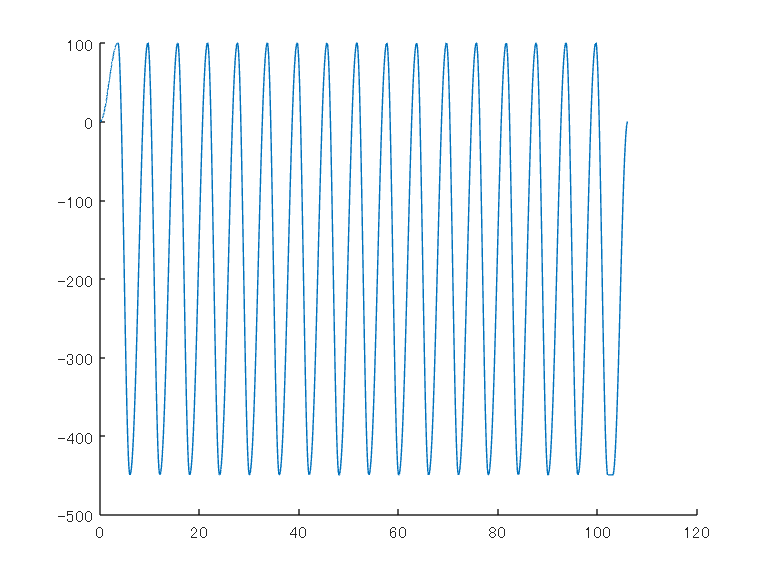

    
    L = stockSlideForwardLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeF = 0; % 単位 (s)
    clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    positionF = stockSlideForwardLength; % 単位 (mm)
    positionB = -stockSlideBackwardLength; % 単位 (mm)
    
    clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeFList; clockTimeBList];
    clockTime = tmp(:);
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    tmp = [deltaTimeFList; deltaTimeBList];
    deltaTime = tmp(:);
    positionFList = positionF + 0*clockTimeFList;
    positionBList = positionB + 0*clockTimeBList;
    tmp = [positionFList; positionBList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    stockRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockRightSlider, "stockRightSlider.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);
end

左ストック 前後傾

if (profile ~= Profile.doubleStock) && (profile ~= Profile.doubleStockOnly)
    LF = tiltForwardDeg; % 単位 (deg)
    LB = tiltBackwardDeg; % 単位 (deg)
    startClockTimeLeftTilt = period/2; % 開始時刻 (s)
    clockTimeB = 0; % 単位 (s)
    clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    positionB = LB; % 単位 (deg)
    positionF = LF; % 単位 (deg)
    
    clockTimeBList = (startClockTimeLeftTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = (startClockTimeLeftTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeBList; clockTimeFList];
    clockTime = tmp(:);
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    tmp = [deltaTimeBList; deltaTimeFList];
    deltaTime = tmp(:);
    positionBList = positionB + 0*clockTimeBList;
    positionFList = positionF + 0*clockTimeFList;
    tmp = [positionBList; positionFList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    leftTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(leftTilt, "leftTilt.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

    LF = tiltForwardDeg; % 単位 (deg)
    LB = tiltBackwardDeg; % 単位 (deg)
    startClockTimeRightTilt = 0; % 開始時刻 (s)
    clockTimeB = 0; % 単位 (s)
    clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    positionB = LB; % 単位 (deg)
    positionF = LF; % 単位 (deg)
    
    clockTimeBList = (startClockTimeRightTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = (startClockTimeRightTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeBList; clockTimeFList];
    clockTime = tmp(:);
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    tmp = [deltaTimeBList; deltaTimeFList];
    deltaTime = tmp(:);
    positionBList = positionB + 0*clockTimeBList;
    positionFList = positionF + 0*clockTimeFList;
    tmp = [positionBList; positionFList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    rightTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(rightTilt, "rightTilt.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);
elseif (profile == Profile.doubleStock) || (profile == Profile.doubleStockOnly)
    LF = tiltForwardDeg; % 単位 (deg)
    LB = tiltBackwardDeg; % 単位 (deg)
    startClockTimeLeftTilt = 0; % 開始時刻 (s)
    clockTimeB = 0; % 単位 (s)
    clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    positionB = LB; % 単位 (deg)
    positionF = LF; % 単位 (deg)
    
    clockTimeBList = (startClockTimeLeftTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = (startClockTimeLeftTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeBList; clockTimeFList];
    clockTime = tmp(:);
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    tmp = [deltaTimeBList; deltaTimeFList];
    deltaTime = tmp(:);
    positionBList = positionB + 0*clockTimeBList;
    positionFList = positionF + 0*clockTimeFList;
    tmp = [positionBList; positionFList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    leftTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(leftTilt, "leftTilt.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

leftTilt = 33×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         3          3.6               5                0      
       6.6          2.4             -30                0      
         9          3.6               5                0      
      12.6          2.4             -30                0      
        15          3.6               5                0      
      18.6          2.4             -30                0      
        21          3.6               5                0      
      24.6          2.4             -30                0      
        27          3.6               5                0      
      30.6          2.4             -30                0      
        33          3.6               5                0      
      36.6          2.4             -30                0      
        39          3.6               5                0      
      42.6          2.4         

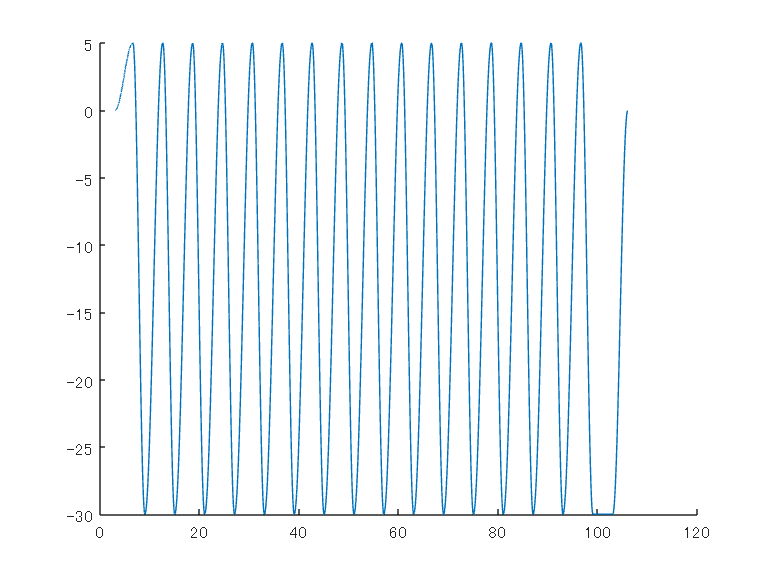

rightTilt = 35×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0          3.6               5                0      
       3.6          2.4             -30                0      
         6          3.6               5                0      
       9.6          2.4             -30                0      
        12          3.6               5                0      
      15.6          2.4             -30                0      
        18          3.6               5                0      
      21.6          2.4             -30                0      
        24          3.6               5                0      
      27.6          2.4             -30                0      
        30          3.6               5                0      
      33.6          2.4             -30                0      
        36          3.6               5                0      
      39.6          2.4        

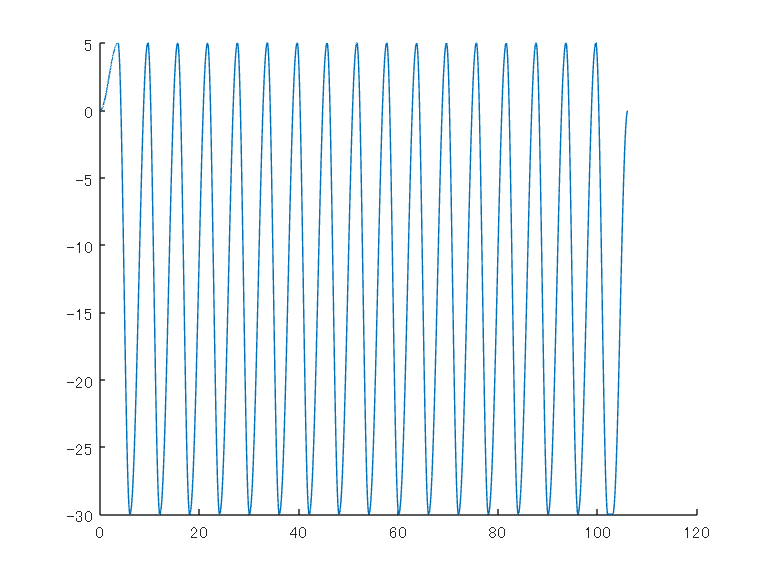

    LF = tiltForwardDeg; % 単位 (deg)
    LB = tiltBackwardDeg; % 単位 (deg)
    startClockTimeRightTilt = 0; % 開始時刻 (s)
    clockTimeB = 0; % 単位 (s)
    clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    deltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
    positionB = LB; % 単位 (deg)
    positionF = LF; % 単位 (deg)
    
    clockTimeBList = (startClockTimeRightTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
    clockTimeFList = (startClockTimeRightTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
    clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
    tmp = [clockTimeBList; clockTimeFList];
    clockTime = tmp(:);
    deltaTimeBList = deltaTimeB + 0*clockTimeBList;
    deltaTimeFList = deltaTimeF + 0*clockTimeFList;
    tmp = [deltaTimeBList; deltaTimeFList];
    deltaTime = tmp(:);
    positionBList = positionB + 0*clockTimeBList;
    positionFList = positionF + 0*clockTimeFList;
    tmp = [positionBList; positionFList];
    absolutePosition = tmp(:);
    
    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    
    useStiffness = zeros(size(clockTime));
    
    rightTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(rightTilt, "rightTilt.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);
end

TiltCSV = table(period, tiltBackwardDeg, tiltForwardDeg, tiltBackwardTimeRate, tiltForwardTimeRate, startClockTimeLeftTilt, startClockTimeRightTilt)

TiltCSV = 1×7 table
    period    tiltBackwardDeg    tiltForwardDeg    tiltBackwardTimeRate    tiltForwardTimeRate    startClockTimeLeftTilt    startClockTimeRightTilt
    ______    _______________    ______________    ____________________    ___________________    ______________________    _______________________

      6              5                -30                   2                       3                       3                          0           


writetable(TiltCSV, 'tilt.csv');

signal_lifter = timeseries(lifter_x, lifter_t, Name='lifter');
signal_leftPedal = timeseries(leftPedal_x, leftPedal_t, Name='leftPedal');
signal_rightPedal = timeseries(rightPedal_x, rightPedal_t, Name='rightPedal');
signal_seatLeftSlider = timeseries(seatLeftSlider_x, seatLeftSlider_t, Name='seatLeftSlider');
signal_seatRightSlider = timeseries(seatRightSlider_x, seatRightSlider_t, Name='seatRightSlider');
signal_stockLeftSlider = timeseries(stockLeftSlider_x, stockLeftSlider_t, Name='stockLeftSlider');
signal_stockRightSlider = timeseries(stockRightSlider_x, stockRightSlider_t, Name='stockRightSlider');
signal_stockLeftExtend = timeseries(stockLeftExtend_x, stockLeftExtend_t, Name='stockLeftExtend');
signal_stockRightExtend = timeseries(stockRightExtend_x, stockRightExtend_t, Name='stockRightExtend');
signal_leftTilt = timeseries(leftTilt_x, leftTilt_t, Name="leftTilt");
signal_rightTilt = timeseries(rightTilt_x, rightTilt_t, Name="rightTilt");

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = signal_lifter;
Scenario{2} = signal_leftPedal;
Scenario{3} = signal_rightPedal;
Scenario{4} = signal_seatLeftSlider;
Scenario{5} = signal_seatRightSlider;
Scenario{6} = signal_stockLeftExtend;
Scenario{7} = signal_stockRightExtend;
Scenario{8} = signal_stockLeftSlider;
Scenario{9} = signal_stockRightSlider;
Scenario{10} = signal_leftTilt;
Scenario{11} = signal_rightTilt;


% Scenario{2} = SignalStickRightPitch;
% Scenario{2}.Name = 'SignalStickRightPitch';
% Scenario{5} = signal_stockLeftPitch;
% Scenario{5}.Name = 'SignalStickLeftPitch';

save('../../../scenario.mat', 'Scenario');

sim("Simulink.slx");

clear;

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end